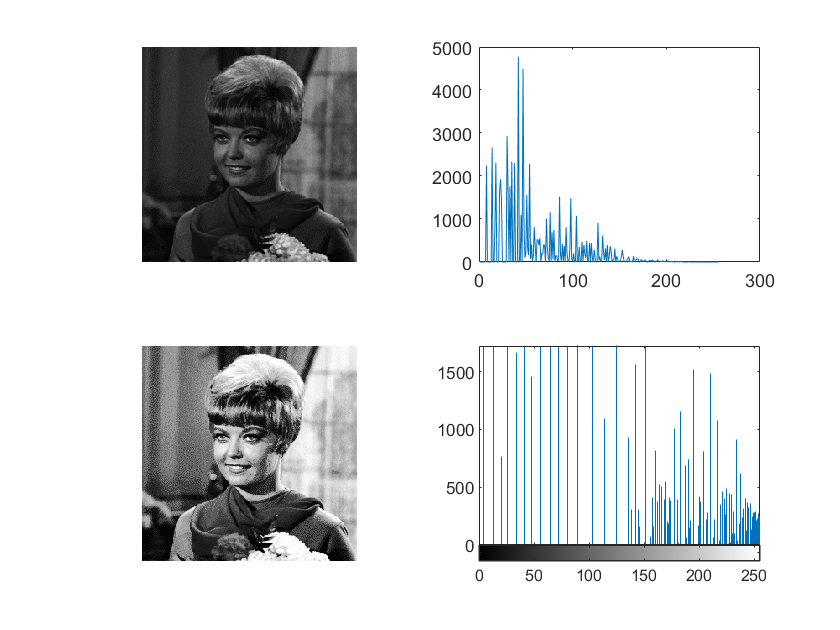

f=imread(['fig3.bmp']);
h1=imhist(f,256);
h2=histeq(f,256);  %histeq均衡后得到为图像
figure(1)
subplot(2,2,1);imshow(f);
subplot(2,2,2);plot(h1);
subplot(2,2,3);imshow(h2);
subplot(2,2,4);imhist(h2); 

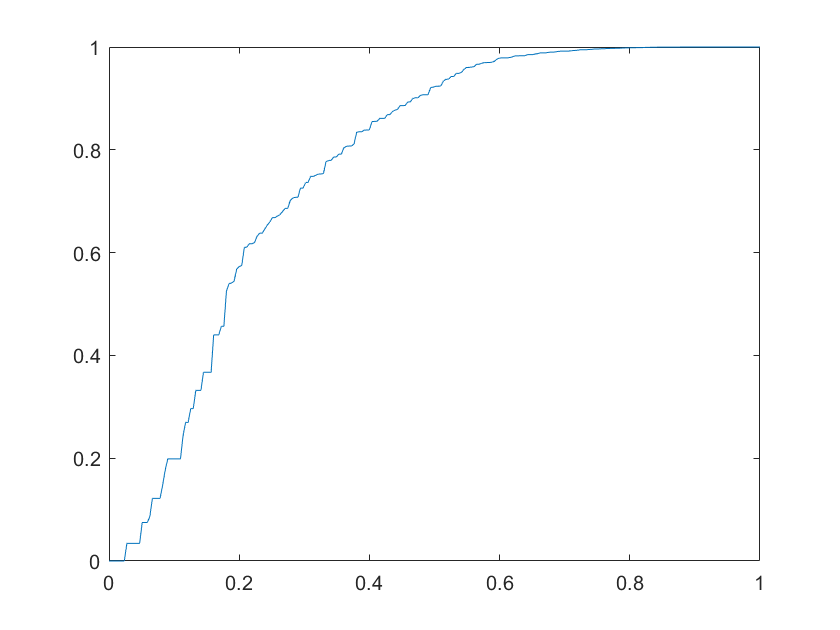

 
hnorm=imhist(f)./numel(f);  %注意为原图像的概率，不是均衡后的
cdf=cumsum(hnorm);  % 变换函数S=T（r）
x=linspace(0,1,256);
figure(2)
plot(x,cdf);
axis([0 1 0 1])
set(gca,'xtick',0:0.2:1)
set(gca,'ytick',0:0.2:1)